clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("测试excel.xlsx");
num(4:5,:)=[];
x = num(8,~isnan(num(8,:)));
y = num(9,~isnan(num(9,:)));
z = num(7,~isnan(num(7,:)));
azimuth = num(4,1);
elevation = num(4,2);
Points = [x;y;z];

PAB = Points(:,5);
% P1 = num(1,[3,4,2]);
% P2 = num(2,[3,4,2]);


P1 = [0.456,1.316,-0.783];
P2 = [0.463,0.431,-0.256];

## 复测数据

% xx = num(13,~isnan(num(13,:)));
% yy = num(14,~isnan(num(14,:))); 
% zz = num(12,~isnan(num(12,:)));
% PointFC = [xx;yy;zz];
% scatter3(xx,yy,zz,50,'filled','yellow')

## 拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);

## A、B面点测试

numShengLu = 4;
phi = deg2rad(65);

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = ShengLuJiaoJiSuan(numShengLu)

Ang =     0.9425    0.3142   -0.3142   -0.9425   -0.9425   -0.3142    0.3142    0.9425



[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest2(MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff)

E xyz: -0.903100, -0.369534, 0.218758
AngOring: 0.008775
A1 xyz: 0.346781, 0.729099, -0.804869


PointTable_A_off =     0.3468    0.0482   -0.3231   -0.6253   -0.6310   -0.3323    0.0390    0.3411
    0.7291    0.5264    0.5232    0.7206    1.3679    1.5706    1.5738    1.3764
   -0.8049   -0.9389   -0.9389   -0.8049   -0.3711   -0.2370   -0.2370   -0.3711


PointTable_B_off =     0.3443    0.0442   -0.3271   -0.6277   -0.6285   -0.3283    0.0430    0.3436
    1.0109    0.9823    0.9791    1.0023    1.0861    1.1147    1.1179    1.0947
   -0.9753   -1.2148   -1.2148   -0.9753   -0.2006    0.0388    0.0388   -0.2006


## 复测函数

% [Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(PointFC,numShengLu,Mcenter,MTaon,Mradial,phi)

## 绘图验证

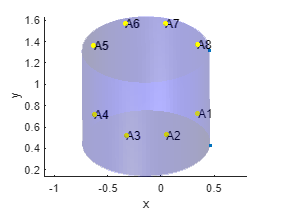

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
% scatter3(Points(1,:),Points(2,:),Points(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");

PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
% scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')
text(PointTable_A_off(1,1),PointTable_A_off(1,2),PointTable_A_off(1,3),'A1')
text(PointTable_A_off(2,1),PointTable_A_off(2,2),PointTable_A_off(2,3),'A2')
text(PointTable_A_off(3,1),PointTable_A_off(3,2),PointTable_A_off(3,3),'A3')
text(PointTable_A_off(4,1),PointTable_A_off(4,2),PointTable_A_off(4,3),'A4')
text(PointTable_A_off(5,1),PointTable_A_off(5,2),PointTable_A_off(5,3),'A5')
text(PointTable_A_off(6,1),PointTable_A_off(6,2),PointTable_A_off(6,3),'A6')
text(PointTable_A_off(7,1),PointTable_A_off(7,2),PointTable_A_off(7,3),'A7')
text(PointTable_A_off(8,1),PointTable_A_off(8,2),PointTable_A_off(8,3),'A8')